clear vars
gitHistoryTable = readtable('bootstrap-output.xlsx')

gitHistoryTable = 19057×4 table
      commit            name              date                                      action                               
    __________    _________________    __________    ____________________________________________________________________

    'be957d'      'XhmikosR'           'Oct 2019'    'Update devDependencies. (#29508)'                                  
    '7327eb'      'Martijn Cuppens'    'Oct 2019'    'Fix top level ampersand (#29518)'                                  
    'eb428'       'leshasmp'           'Oct 2019'    'Carousel variables (#29493)'                                       
    'eafd'        'astrahov'           'Oct 2019'    'Group line-height variables (#29466)'                              
    'efcab'       'Jeremy Jackson'     'Oct 2019'    'Add color argument to button mixins (#29444)'

## The top contributors according to git history data

Enter how many of the top contributors you would like to view into the textbox below. Beware the max number of contributors printed to the right.

contributors = categorical(gitHistoryTable.name);
[commitsPerContr, contributors] = histcounts(contributors);
[sortedCommits, newIndices] = sort(commitsPerContr, "descend");
sortedContributors = contributors(newIndices);
disp(['Max number of contributors: ', num2str(length(sortedContributors))])

Max number of contributors: 1276


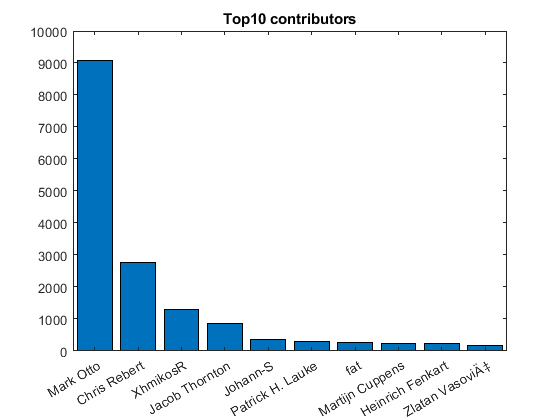

x = 10;
x = round(x);
topxUsers = sortedContributors(1:x);

sortedContributors = categorical(topxUsers, topxUsers);
sortedCommits = sortedCommits(1:x);

bar(sortedContributors, sortedCommits);
s = strcat('Top ', num2str(x), ' contributors');
title(s)

## The number of contributors, commits and commits per contributor.

numContributors = length(contributors);
numCommits = length(gitHistoryTable.commit);
avgCommits = numCommits/numContributors;
disp(['Number of contributors: ', num2str(numContributors)])

Number of contributors: 1276


disp(['Number of commits: ', num2str(numCommits)])

Number of commits: 19057


disp(['Average commits per contributor: ', num2str(avgCommits)])

Average commits per contributor: 14.935


## Commits over time

months = categorical(gitHistoryTable.date);
[commitsPerMonth, months] = histcounts(months);
monthDates = datetime(months);
months = categorical(months, months);
quarters = [];
commitsPerQuarter = [];

plot(monthDates, commitsPerMonth, 'LineWidth', 2);
title('Commits over time');
grid on;
xlabel('Year');
ylabel('Number of commits');

GUI

% s = get(0, 'ScreenSize')
% w = s(3)

s =            1           1        1366         768


% h = s(4)

w = 1366

% startX = w/2 - w/2/2;

h = 768

% startY = h/2 - h/2/2;
% f = figure('Visible','off','Position', [startX, startY, w/2, h/2]);
% 
% f.Visible = 'on';

CallGraph

digraph











